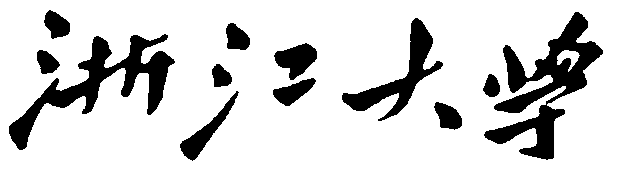

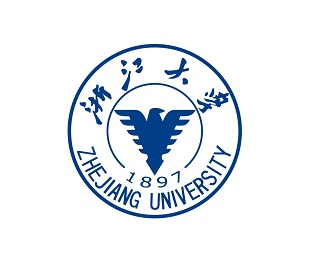

# **本科实验报告**

`|   姓名：   |       沈骏一       |`

`|   学院：   | 控制科学与工程学院 |`

`|   专业：   |   自动化（控制）   |`

`|   学号：   |     3200100259     |`

`| 指导教师： |        姜伟        |`

## `2023年6月18日`

## `数字图像处理与机器视觉--视差估计`

## 基于块匹配的双目视差估计方法

### 块匹配

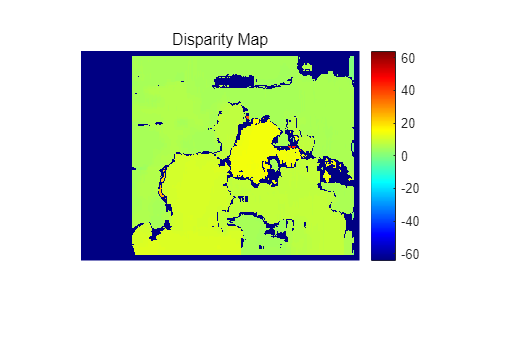

% 读取左右图像（灰度图像）
left_image = imread('tsukuba_l.png');
right_image = imread('tsukuba_r.png');

% 如果需要，将图像转换为灰度图像
if size(left_image, 3) > 1
    left_image = rgb2gray(left_image);
end
if size(right_image, 3) > 1
    right_image = rgb2gray(right_image);
end

% 设置视差计算参数
num_disparities = [0,64];  % 视差范围
block_size = 15;       % 块大小

% 使用块匹配算法计算视差图
disparity_map = disparityBM(left_image, right_image, 'DisparityRange', num_disparities, 'BlockSize', block_size);

% 显示视差图
figure;
imshow(disparity_map, disparity_range);
colormap('jet');
colorbar;
title('Disparity Map');

**块匹配（Block Matching）**是一种常用的双目视差估计方法，用于找到左右图像中对应像素的视差值。其基本原理是将图像划分为一系列的像素块，在左图像中选取一个像素块作为参考块，然后在右图像中搜索与参考块最相似的块，并计算它们之间的视差值。

块匹配方法的优势：

- 简单直观：块匹配方法易于理解和实现，计算过程相对简单。

- 计算速度较快：相对于一些复杂的视差估计算法，块匹配方法计算速度较快，适用于实时应用和资源受限的环境。

- 适用于纹理丰富的区域：在具有良好纹理结构的区域，块匹配方法能够产生准确的视差估计结果。

块匹配方法的劣势：

- 对纹理较差的区域效果较差：在纹理较差或重复结构的区域，块匹配方法容易产生误匹配，导致视差估计不准确。

- 无法处理非唯一匹配：当出现多个相似块与参考块匹配程度相近时，块匹配方法无法确定最准确的匹配，可能产生误匹配。

- 对视差变化较大的区域效果较差：在深度变化较大的区域，块匹配方法可能无法正确匹配对应的像素块，导致视差估计不准确。

### SGM（半全局匹配）

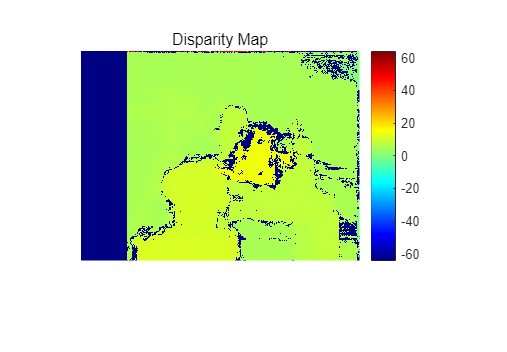

% 读取左右图像（灰度图像）
left_image = imread('tsukuba_l.png');
right_image = imread('tsukuba_r.png');

% 如果需要，将图像转换为灰度图像
if size(left_image, 3) > 1
    left_image = rgb2gray(left_image);
end
if size(right_image, 3) > 1
    right_image = rgb2gray(right_image);
end

% 设置视差计算参数
num_disparities = [0,64];  % 视差范围

% 使用半全局匹配算法计算视差图
disparity_map = disparitySGM(left_image, right_image, 'DisparityRange', num_disparities);

% 显示视差图
figure;
imshow(disparity_map, disparity_range);
colormap('jet');
colorbar;
title('Disparity Map');

**SGM（Semi-Global Matching）匹配方法**是一种基于全局优化的双目视差估计方法，通过考虑多个视差值和像素的一致性来提高匹配的准确性。它在块匹配的基础上引入了全局能量优化，以解决块匹配方法在纹理较差、非唯一匹配和视差变化较大区域下的不足。

SGM匹配方法的优势：

- 全局一致性：SGM方法通过考虑多个像素的一致性，能够在块匹配的基础上减少误匹配，提高视差估计的准确性。

- 大视差范围：SGM方法可以处理较大的视差范围，适用于场景中深度变化较大的区域。

- 抗噪性较好：由于全局优化的引入，SGM方法对图像噪声的影响较小，具有较好的抗噪性能。

SGM匹配方法的劣势：

- 计算复杂度较高：相对于块匹配方法，SGM方法的计算复杂度较高，需要进行全局能量优化，可能导致较长的计算时间。

- 参数调节较为复杂：SGM方法涉及一些参数的调节，如代价聚合权重、视差平滑参数等，需要进行适当的调试和优化才能获得较好的结果。

- 对纹理较差的区域效果有限：虽然SGM方法在纹理丰富的区域表现良好，但在纹理较差的区域，仍可能产生误匹配或不准确的视差估计。

除了以上两个函数，还可以使用`disparity`函数并设定参数值来实现深度图的获取。

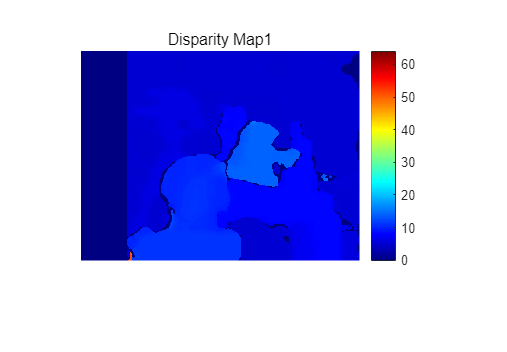

% 读取左右图像（灰度图像）
left_image = imread('tsukuba_l.png');
right_image = imread('tsukuba_r.png');

% 设置视差计算参数
num_disparities = 64;     % 视差范围

% 计算视差图
disparity_map1 = disparity(left_image, right_image, ...
    'Method','SemiGlobal',...
    'DisparityRange', [0, num_disparities]);

disparity_map2 = disparity(left_image, right_image, ...
    'Method','BlockMatching',...
    'DisparityRange', [0, num_disparities]);

% 可视化视差图
figure;
imshow(disparity_map1, [0,num_disparities]);
colormap('jet');
colorbar;
title('Disparity Map1');

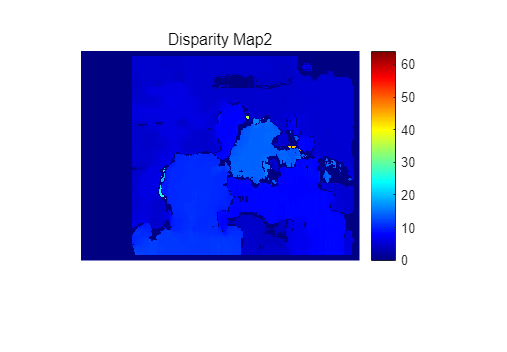

imshow(disparity_map2, [0,num_disparities]);
colormap('jet');
colorbar;
title('Disparity Map2');

## 基于特征匹配的方法

### SIFT

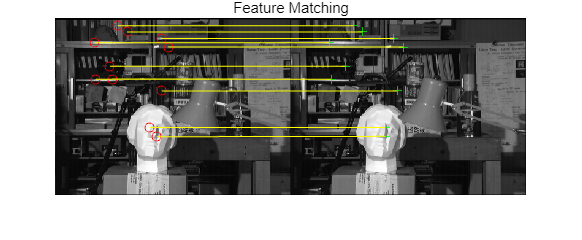

% 读取左右图像（灰度图像）
left_image = imread('tsukuba_l.png');
right_image = imread('tsukuba_r.png');

% 创建 SIFT 特征检测器
sift = detectSIFTFeatures(left_image);

% 提取 SIFT 特征描述子
[features_left, valid_points_left] = extractFeatures(left_image, sift);
[features_right, valid_points_right] = extractFeatures(right_image, sift);

% 使用暴力匹配器进行特征匹配
matcher = matchFeatures(features_left, features_right);

% 获取匹配点对的索引
matched_pts_left = valid_points_left(matcher(:, 1)).Location;
matched_pts_right = valid_points_right(matcher(:, 2)).Location;

% 计算视差图
disparity_range = [-64 64]; % 视差范围
disparity_map = disparity(left_image, right_image, 'BlockSize', 15, 'DisparityRange', disparity_range);

% 显示匹配结果
figure;
showMatchedFeatures(left_image, right_image, matched_pts_left, matched_pts_right, 'montage');
title('Feature Matching');

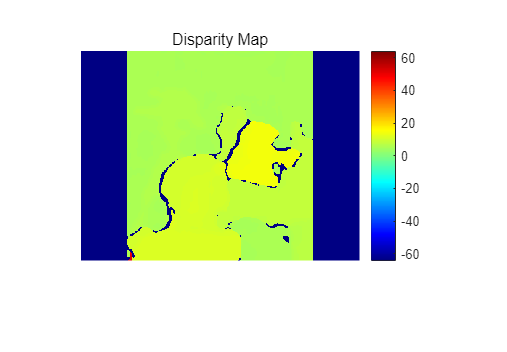


% 显示视差图
figure;
imshow(disparity_map, disparity_range);
colormap('jet');
colorbar;
title('Disparity Map');

**SIFT（尺度不变特征变换）**是一种常用的特征匹配方法，用于在图像中检测和描述局部特征。它的主要步骤包括尺度空间极值检测、关键点定位、方向分配、描述子生成和特征匹配。

SIFT 特征匹配的优势包括：

- 尺度不变性：SIFT 特征可以在不同尺度下检测和匹配，对于尺度变换（例如物体的缩放或旋转）具有较好的不变性。

- 旋转不变性：SIFT 特征可以在不同角度下检测和匹配，对于物体的旋转变换具有较好的不变性。

- 鲁棒性：SIFT 特征对于光照变化、仿射变换和噪声具有一定的鲁棒性，可以在复杂的图像环境下进行有效的匹配。

- 匹配精度高：SIFT 特征使用局部图像区域的描述子进行匹配，具有较高的匹配精度。

然而，SIFT 特征匹配也存在一些劣势：

- 计算复杂度高：SIFT 特征提取和匹配过程中涉及到大量的图像处理和计算操作，因此对于大规模图像数据或实时应用可能会较为耗时。

- 冗余特征点：SIFT 特征提取可能会生成一些冗余的特征点，这些特征点可能对匹配过程产生干扰或降低匹配的准确性。

- 参数设置敏感：SIFT 特征匹配的性能对参数的设置较为敏感，不同的参数组合可能导致不同的匹配结果，需要进行调优。

### SURF

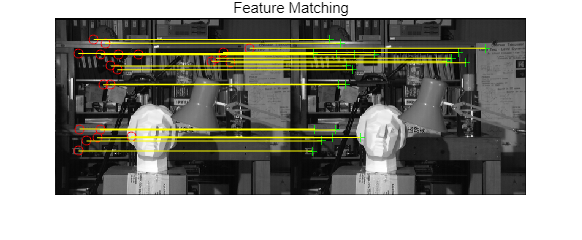

% 读取左右图像（灰度图像）
left_image = imread('tsukuba_l.png');
right_image = imread('tsukuba_r.png');

% 创建 SURF 特征检测器
surf = detectSURFFeatures(left_image);

% 提取 SURF 特征描述子
[features_left, valid_points_left] = extractFeatures(left_image, surf);
[features_right, valid_points_right] = extractFeatures(right_image, surf);

% 使用暴力匹配器进行特征匹配
matcher = matchFeatures(features_left, features_right);

% 获取匹配点对的索引
matched_pts_left = valid_points_left(matcher(:, 1)).Location;
matched_pts_right = valid_points_right(matcher(:, 2)).Location;

% 计算视差图
disparity_range = [-64 64]; % 视差范围
disparity_map = disparity(left_image, right_image, 'BlockSize', 15, 'DisparityRange', disparity_range);

% 显示匹配结果
figure;
showMatchedFeatures(left_image, right_image, matched_pts_left, matched_pts_right, 'montage');
title('Feature Matching');


% 显示视差图
figure;
imshow(disparity_map, disparity_range);
colormap('jet');
colorbar;
title('Disparity Map');

**SURF（加速稳健特征）**是一种用于图像特征检测和匹配的方法，它在尺度空间中寻找稳定的局部特征点，并生成描述子进行匹配。SURF 方法是对 SIFT 方法的改进，旨在提供更快速和稳健的特征匹配。

SURF 特征匹配的优势包括：

- 快速性能：相比于 SIFT，SURF 采用了一些加速技术，例如使用快速 Hessian 矩阵计算和积分图像，使得 SURF 特征提取和匹配的速度更快。

- 尺度和旋转不变性：SURF 特征通过尺度空间中的盒状滤波器检测稳定的局部特征点，并使用 Haar 小波响应来描述特征点的局部结构。这使得 SURF 对于尺度和旋转变化有较好的不变性。

- 鲁棒性：SURF 方法在光照变化、视角变化和部分遮挡等情况下表现较好，对于复杂的图像场景具有一定的鲁棒性。

- 少量特征点：相对于 SIFT，SURF 通常生成较少的特征点，这可以减少计算量并提高匹配效率。

然而，SURF 特征匹配也存在一些劣势：

- 对于噪声敏感：SURF 特征对图像噪声比较敏感，可能会导致误匹配或不稳定的匹配结果。

- 参数依赖性：SURF 方法依赖于一些参数设置，例如尺度空间的层数和特征点的阈值等。不同的参数选择可能会对匹配结果产生影响，需要进行调优。

- 有限的旋转不变性：尽管 SURF 对于某些程度的旋转变化具有不变性，但对于较大的旋转角度可能会失效。

## 基于光流的方法

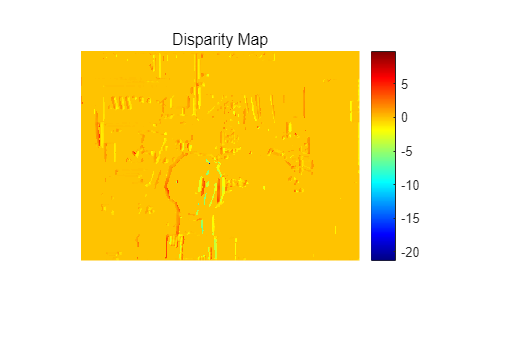

% 读取左右图像（灰度图像）
left_image = imread('tsukuba_l.png');
right_image = imread('tsukuba_r.png');

% 使用光流法计算视差
opticFlow = opticalFlowLK('NoiseThreshold',0.01);
flow = estimateFlow(opticFlow, left_image);

% 计算视差图
disparity_map = -flow.Vx;

% 显示视差图
figure;
imshow(disparity_map,[]);
colormap('jet');
colorbar;
title('Disparity Map');

**基于光流的方法**是一种使用光流估计技术来计算视差图的方法。光流是指描述图像中像素在连续帧之间的运动方向和速度的信息。通过计算图像中的光流场，可以推导出像素之间的视差，从而构建视差图。

基于光流的方法构建视差图的优势包括：

- 非匹配方法：与传统的基于特征匹配的方法不同，光流方法直接计算像素之间的运动信息，不需要进行特征点的匹配，因此可以更快速地生成视差图。

- 实时性能：光流方法通常具有较高的实时性能，特别适用于需要实时视差估计的应用，如自动驾驶、机器人导航等。

- 对纹理较少的区域有效：光流方法在纹理较少的区域仍然能够提供合理的视差估计，相比于基于特征的方法更具优势。

然而，基于光流的方法也存在一些劣势：

- 光流的稠密计算：光流方法需要在整个图像上计算每个像素的运动信息，这导致计算量较大，尤其对于高分辨率图像和复杂场景，计算时间会增加。

- 对快速运动和遮挡敏感：光流方法对于快速运动的物体和存在遮挡的区域容易产生错误的光流估计，从而导致视差图中的估计错误。

- 光流失真：由于光流计算是基于一些假设和约束条件的，例如亮度恒定和平滑性假设，当这些假设不成立时，光流计算可能会失真，从而影响视差图的准确性。